# **GWSAT DETUMBLING ALGORITHM**

## **1 Get Earth Magnetic Field**

The calculated values for the Earth's magnetic field using World Magnetic Model 2020 (WMM2020) overlaid on maps of the Earth.

The Mapping Toolbox™ is required to generate the maps of the Earth. The following code will be capable to obtain the following parameters ontained during the satellite orbit.

- X- North component of magnetic field vector in nanotesla (nT)

- Y - East component of magnetic field vector in nanotesla (nT)

- Z - Down component of magnetic field vector in nanotesla (nT)

- H - Horizontal intensity in nanotesla (nT)

- DEC - Declination in degrees

- DIP - Inclination in degrees

- F - Total intensity in nanotesla (nT)

Start orbit propagator

startTime = datetime(2023,08,30,12,35,38);
stopTime = startTime + hours(8.5);
sampleTime = 60;
sc = satelliteScenario(startTime,stopTime,sampleTime);

Set satellite orbital parameters

orbit.semiMajorAxis = 500E3+6378E3;
orbit.eccentricity = 0;
orbit.inclination = 97.34; 
orbit.rightAscensionOfAscendingNode = 313.131; 
orbit.argumentOfPeriapsis = 0; 
orbit.trueAnomaly = 0; 

Create satellite 

satSGP4 = satellite(sc, orbit.semiMajorAxis, orbit.eccentricity, orbit.inclination, ...
        orbit.rightAscensionOfAscendingNode, orbit.argumentOfPeriapsis, orbit.trueAnomaly);

 Obtain Satellite translational Dyamics in the Longitudinal coordinates.

[positionSGP4,~,timeSGP4] = states(satSGP4,"CoordinateFrame", "geographic");

Get the model reference model based on WMM model with these wrldmagm inputs:

- model_epoch - Epoch of WMM model.

- decimal_year - Scalar value representing the decimal year within the epoch for which the data was generated.

model_epoch = '2020';       %WMM2020     (2020-2025) (default)
decimal_year = 2023;
wgs84 = wgs84Ellipsoid;
%% Initialize array to store results
WMMResults = zeros(length(positionSGP4),10);

Get the earth magnetic intensity taking into account the position of the satellite.

 for i = 1:length(positionSGP4)

To obtain magnetic parameters for each latitude and longitude value, use the wrldmagm function.

     [xyz, h, dec, dip, f] = wrldmagm(positionSGP4(3,i), positionSGP4(1,i),positionSGP4(2,i), decimal_year, model_epoch);             

Transform magnetic field expressed in NED frame into ECEF frame.

     [x1,y1,z1] = ned2ecef(0,0,0,positionSGP4(1,i),positionSGP4(2,i),positionSGP4(3,i),wgs84);
     [x2,y2,z2] = ned2ecef(xyz(1)*1E-9,xyz(2)*1E-9,xyz(3)*1E-9,positionSGP4(1,i),positionSGP4(2,i),positionSGP4(3,i),wgs84);

    Store the results in WMMResults variable.

     WMMResults(i,1:10) = [(x2-x1)*1E9, (y2-y1)*1E9, (z2-z1)*1E9, xyz', h, dec, dip, f];
 end 

Plot magnetic components

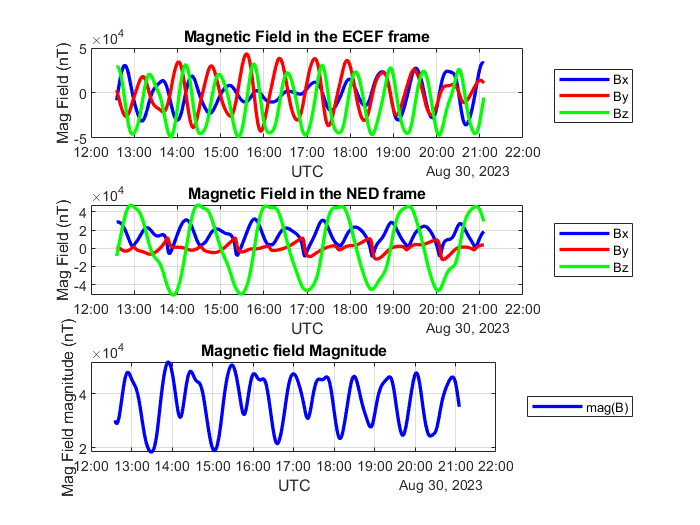

%%Plot Magnetic Field components
figure();
subplot(3,1,1)
    p1 = plot(timeSGP4,WMMResults(:,1),'b-','LineWidth',2); hold on; grid on
    p2 = plot(timeSGP4,WMMResults(:,2),'r-','LineWidth',2);
    p3 = plot(timeSGP4,WMMResults(:,3),'g-','LineWidth',2);
    legend([p1,p2,p3],'Bx','By','Bz','Location','eastoutside')
    xlabel('UTC')
    ylabel('Mag Field (nT)')
    title('Magnetic Field in the ECEF frame')
    %%Plot Magnetic Field magnitudE
subplot(3,1,2)
    p1 = plot(timeSGP4,WMMResults(:,4),'b-','LineWidth',2); hold on; grid on
    p2 = plot(timeSGP4,WMMResults(:,5),'r-','LineWidth',2);
    p3 = plot(timeSGP4,WMMResults(:,6),'g-','LineWidth',2);
    legend([p1,p2,p3],'Bx','By','Bz','Location','eastoutside')
    xlabel('UTC')
    ylabel('Mag Field (nT)')
    title('Magnetic Field in the NED frame')
    %%Plot Magnetic Field magnitude
    

subplot(3,1,3)
    p1 = plot(timeSGP4,WMMResults(:,10),'b-','LineWidth',2); hold on; grid on;
    legend(p1,'mag(B)','Location','eastoutside');
    xlabel('UTC')
    ylabel('Mag Field magnitude (nT)')
    title('Magnetic field Magnitude')

Calculate the magnetic field norm in order to evaluate if the reference convertion is done correctly.

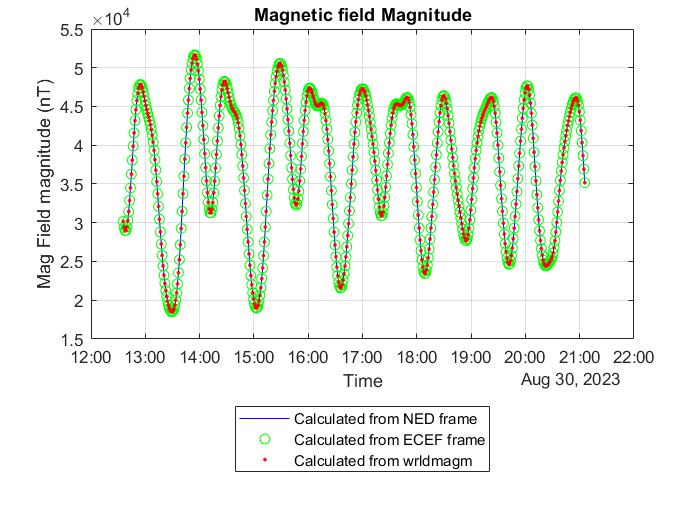

magField_NED = zeros(1,length(WMMResults));
magField_ECEF= zeros(1,length(WMMResults));
for i = 1:length(WMMResults)
    magField_NED(i)  = norm(WMMResults(i,4:6));
    magField_ECEF(i) = norm(WMMResults(i,1:3));
end
figure()
p1 = plot(timeSGP4,magField_NED,'b-'); hold on;

p2 = plot(timeSGP4,magField_ECEF,'go'); 
p3 = plot(timeSGP4,WMMResults(:,10),'r.');
xlabel('Time'); ylabel('Mag Field magnitude (nT)');
title('Magnetic field Magnitude');
legend([p1,p2,p3],'Calculated from NED frame','Calculated from ECEF frame','Calculated from wrldmagm','Location','southoutside')
grid on

Get ECEF coordinates to perform 3D plot of the magnetic Field.

positionSGP4ecef = states(satSGP4,"CoordinateFrame", "ecef");

Plot magnetic field 3D.

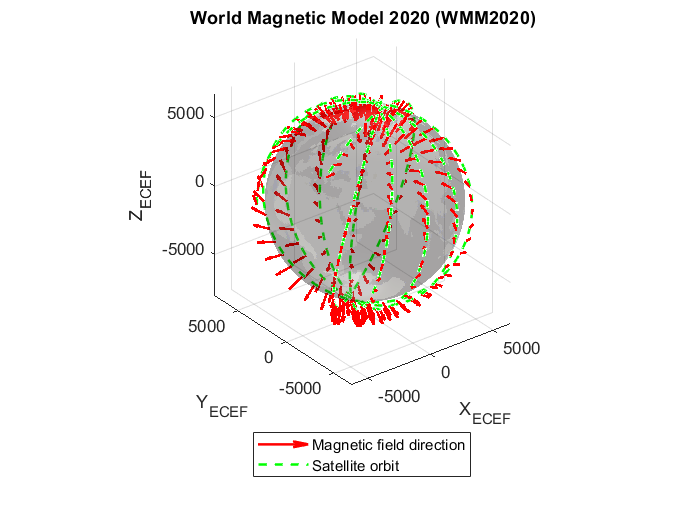

%%%%This will define all of our planet parameters
earth.Radius       = 6378E3;               %% Planet Radius (meters)
earth.Mass         = 5.972E24;             %% Planet Mass (kg)
earth.GravityConst = 6.674E-11;            %% Planet gravity constan (Nm^2/kg^2)
earth.mu           = earth.GravityConst*earth.Mass;        %% G*M product (Nm^2/kg)

figure()
%%%Build Earth
    %%%Load earth elevation data
    load('topo.mat', 'topo', 'topomap1');
    %%%Obtain elevation data size
    [rows, cols] = size(topo);
    %%%Create 3D earth sphere
    [X, Y, Z] = sphere(rows-1, cols-1);
    X = X*earth.Radius/1000;
    Y = Y*earth.Radius/1000;
    Z = Z*earth.Radius/1000;    
    surf(X, Y, Z,topo,'EdgeColor', 'none', 'FaceColor', 'texturemap', 'CDataMapping', 'direct','FaceAlpha',0.2);
    grid on; hold on; axis equal;
    colormap(topomap1);
    %%%Set view and ilumination
    light('Position', [1 1 1]);
    lighting gouraud;
    view(3);
    %%%Add title
    title('3D Orbit in ECEF')
    
h1 = plot3(positionSGP4ecef(1,:)*1E-3,positionSGP4ecef(2,:)*1E-3,positionSGP4ecef(3,:)*1E-3,'g--','LineWidth',1.5);
for  i = 1:length(positionSGP4ecef)
    if (mod(i,2)==1)
        [h2,~] = plotVector(positionSGP4ecef(:,i)*1E-3,WMMResults(i,1:3)*3E-2,1,'r-','','e'); 
        set(h2,'LineWidth',1.5,'MaxHeadSize',2);
    end

end
xlabel('X_{ECEF}'); ylabel('Y_{ECEF}'); zlabel('Z_{ECEF}');
title('World Magnetic Model 2020 (WMM2020)');
legend([h2,h1],'Magnetic field direction','Satellite orbit','Location','southoutside')

### **1.1. Evaluate Magnetic Field Reference Frames**

#### **1.1.1. NED Frame**

Evaluate the magnetic Field in the stop Time so first we need to evaluate satellite position.

[positionSGP4,velocitySGP4,timeSGP4] = states(satSGP4,stopTime,"CoordinateFrame", "geographic");

Evaluate the magnetic field and it is obtained in bady frame.

[xyz, h, dec, dip, f] = wrldmagm(positionSGP4(3), positionSGP4(1),positionSGP4(2), decimal_year, model_epoch);             

Plot the Magnetic Fiel in NED Frame

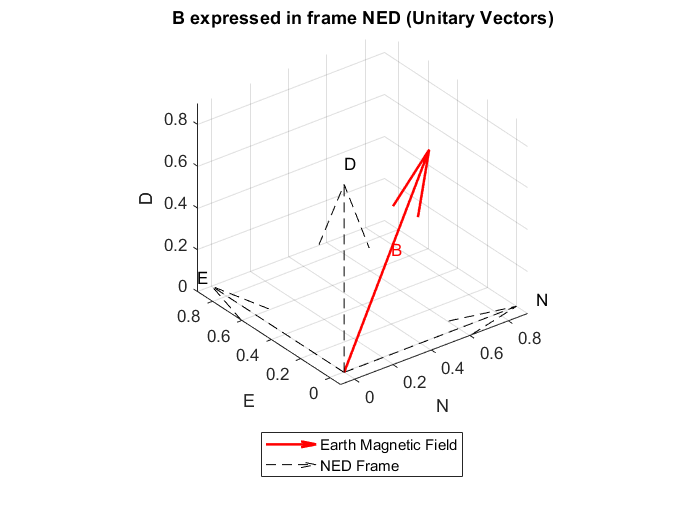

figure()
%%Plot Magnetic field
[h1,~] = plotVector(zeros(1,3),getUnitVector(xyz),1,'r-','B','m'); hold on
%%Plot NED frame
[h2,~] = plotVector(zeros(1,3),[1,0,0],1,'k--','N','e');
[h3,~] = plotVector(zeros(1,3),[0,1,0],1,'k--','E','e');
[h4,~] = plotVector(zeros(1,3),[0,0,1],1,'k--','D','e');
%%Grafic settings
xlabel('N'); ylabel('E'); zlabel('D');
title('B expressed in frame NED (Unitary Vectors)');
set(h1,'LineWidth',1.5,'MaxHeadSize',1); set(h2,'MaxHeadSize',1);
set(h3,'MaxHeadSize',1); set(h4,'MaxHeadSize',1);
legend([h1,h2],'Earth Magnetic Field','NED Frame','Location','southoutside');
axis equal;

#### **1.1.2 Inertial Frame**

Get Satellite position in the inertial frame.

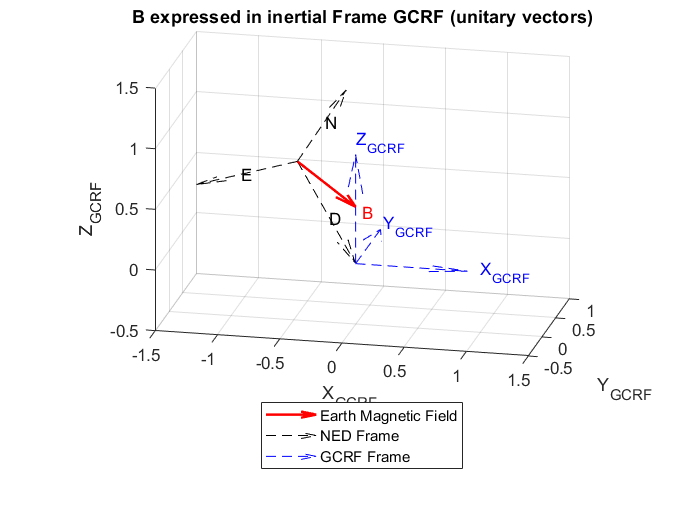

[positionGCRF, velGCRF] = states(satSGP4,stopTime,"CoordinateFrame", "inertial");

%%%Convert NED (North East Down to X,Y,Z in ECI frame)
%%%First we need to create a rotation matrix from the NED frame to the 
%%%inertial frame
phiE = 0;
thetaE = acos(positionGCRF(3)/norm(positionGCRF));
psiE = atan2(positionGCRF(2),positionGCRF(1));
rot_NED_I = TIB(phiE,thetaE+pi,psiE);   %NED to inertial Rotation matrix
    
figure()
%%Plot B vector
[h1,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I*getUnitVector(xyz),1,'r-','B','e'); hold on
set(h1,'LineWidth',1.5,'MaxHeadSize',1);
%%Plot NED frame
[h2,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I(:,1),1,'k--','N','m');
[h3,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I(:,2),1,'k--','E','m');
[h4,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I(:,3),1,'k--','D','m');
set(h2,'MaxHeadSize',1);set(h3,'MaxHeadSize',1);set(h4,'MaxHeadSize',1);
%%Plot GCRF frame
[h5,~] = plotVector(zeros(1,3),[1,0,0],1,'b--','X_{GCRF}','e');
[h6,~] = plotVector(zeros(1,3),[0,1,0],1,'b--','Y_{GCRF}','e');
[h7,~] = plotVector(zeros(1,3),[0,0,1],1,'b--','Z_{GCRF}','e');
set(h5,'MaxHeadSize',1);set(h6,'MaxHeadSize',1);set(h7,'MaxHeadSize',1);
%%%Graphics settings
legend([h1,h2,h5],'Earth Magnetic Field','NED Frame', 'GCRF Frame','Location','southoutside');
xlabel('X_{GCRF}'); ylabel('Y_{GCRF}'); zlabel('Z_{GCRF}');
title('B expressed in inertial Frame GCRF (unitary vectors)'); axis equal;
xlim([-1.5 1.5]);ylim([-0.5 1.0]);zlim([-0.5 1.5]);
view([12.54 17.82]);

#### **1.1.3  Orbit Frame**

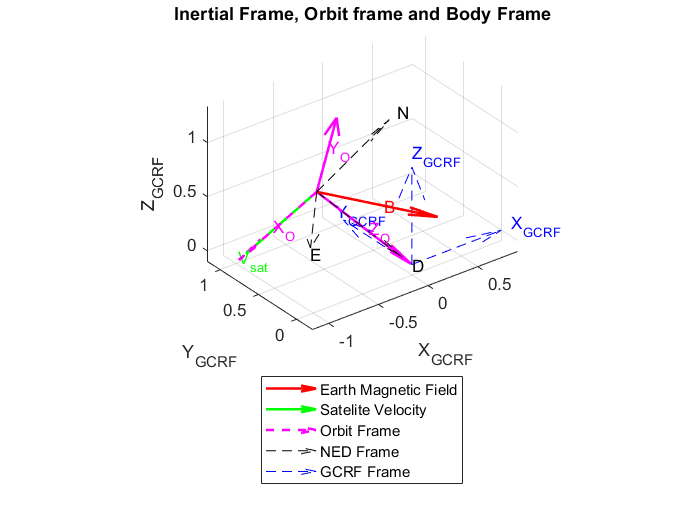

%%Alignt X_o vector in direction of satellite velocity and Zvector to
%%nadir pointing vector
oX=getUnitVector(velGCRF); oZ=-1*getUnitVector(positionGCRF); oY=cross(oZ,oX);
rot_orbit_I=horzcat(oX,oY,oZ);

figure()
%%% Plot satelite velocity and B campus
[h1,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I*getUnitVector(xyz),1,'r-','B','m'); hold on
[h2,~] = plotVector(getUnitVector(positionGCRF),getUnitVector(velGCRF),1,'g.','V_{sat}','e'); hold on
set(h1,'LineWidth',1.5,'MaxHeadSize',1); set(h2,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot orbit frame
[h3,~] = plotVector(getUnitVector(positionGCRF),rot_orbit_I(:,1),1,'m--','X_{O}','m');
[h4,~] = plotVector(getUnitVector(positionGCRF),rot_orbit_I(:,2),1,'m-','Y_{O}','m');
[h5,~] = plotVector(getUnitVector(positionGCRF),rot_orbit_I(:,3),1,'m-','Z_{O}','m');
set(h3,'LineWidth',1.5,'MaxHeadSize',1); set(h4,'LineWidth',1.5,'MaxHeadSize',1); set(h5,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot NED frame
[h6,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I(:,1),1,'k--','N','e');
[h7,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I(:,2),1,'k--','E','e');
[h8,~] = plotVector(getUnitVector(positionGCRF),rot_NED_I(:,3),1,'k--','D','e');
set(h6,'MaxHeadSize',1); set(h7,'MaxHeadSize',1); set(h8,'MaxHeadSize',1);

%%Plot GCRF frame
[h9 ,~]  = plotVector(zeros(1,3),[1,0,0],1,'b--','X_{GCRF}','e');
[h10,~]  = plotVector(zeros(1,3),[0,1,0],1,'b--','Y_{GCRF}','e');
[h11,~]  = plotVector(zeros(1,3),[0,0,1],1,'b--','Z_{GCRF}','e');
set(h9,'MaxHeadSize',1); set(h10,'MaxHeadSize',1); set(h11,'MaxHeadSize',1);

legend([h1,h2,h3,h6,h9],'Earth Magnetic Field','Satelite Velocity','Orbit Frame','NED Frame', 'GCRF Frame','Location','southoutside');
set(h8,'MaxHeadSize',1); set(h9,'MaxHeadSize',1); set(h10,'MaxHeadSize',1);
xlabel('X_{GCRF}'); ylabel('Y_{GCRF}'); zlabel('Z_{GCRF}');
title('Inertial Frame, Orbit frame and Body Frame');

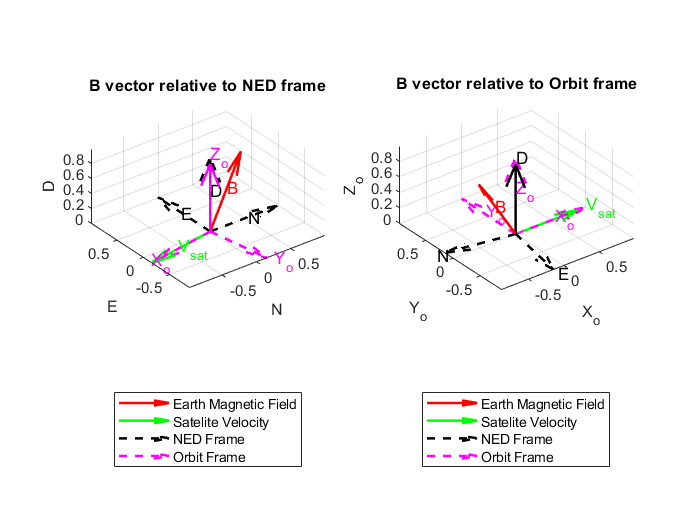

figure()

subplot(1,2,1)
%%% Get rotation quaternion from NED to orbit frame 
D_v = [0,0,1]';
A = norm(cross(rot_NED_I(:,1),getUnitVector(velGCRF)));
B = dot(rot_NED_I(:,1),getUnitVector(velGCRF));
angle = atan2(A,B);
q_NED_o = [cos(angle/2), D_v(1)*sin(angle/2), D_v(2)*sin(angle/2), D_v(3)*sin(angle/2)]; 

%%Plot NED Frame
 [h1,~] = plotVector(zeros(1,3),[1,0,0]',1,'k--','N','m'); hold on;
 [h2,~] = plotVector(zeros(1,3),[0,1,0]',1,'k--','E','m');
 [h3,~] = plotVector(zeros(1,3),[0,0,1]',1,'k--','D','m');
 set(h1,'LineWidth',1.5,'MaxHeadSize',1); set(h2,'LineWidth',1.5,'MaxHeadSize',1); set(h3,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot Sat vel in NED frame
 [h4,~] = plotVector(zeros(1,3),rot_NED_I'*getUnitVector(velGCRF),1,'g-','V_{sat}','m');
 set(h4,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot Orbit frame
 [h5,~] = plotVector(zeros(1,3),quatRotation(quatconj(q_NED_o),[1,0,0]'),1,'m--','X_o','e');
 [h6,~] = plotVector(zeros(1,3),quatRotation(quatconj(q_NED_o),[0,1,0]'),1,'m--','Y_o','e');
 [h7,~] = plotVector(zeros(1,3),quatRotation(quatconj(q_NED_o),[0,0,1]'),1,'m-','Z_o','e');
 set(h5,'LineWidth',1.5,'MaxHeadSize',1); set(h6,'LineWidth',1.5,'MaxHeadSize',1); 
 set(h7,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot B vector
 [h8,~] = plotVector(zeros(1,3),getUnitVector(xyz),1,'r-','B','m');
 set(h8,'LineWidth',1.5,'MaxHeadSize',1);
 
%%Graphics secttings
legend([h8,h4,h1,h5],'Earth Magnetic Field','Satelite Velocity','NED Frame','Orbit Frame','Location','southoutside');
xlabel('N'); ylabel('E'); zlabel('D');
title('B vector relative to NED frame'); axis equal;


subplot(1,2,2)
%%Plot Orbit Frame
 [h1,~] = plotVector(zeros(1,3),[1,0,0]',1,'m--','X_o','m'); hold on;
 [h2,~] = plotVector(zeros(1,3),[0,1,0]',1,'m--','Y_o','m');
 [h3,~] = plotVector(zeros(1,3),[0,0,1]',1,'m--','Z_o','m');
 set(h1,'LineWidth',1.5,'MaxHeadSize',1); set(h2,'LineWidth',1.5,'MaxHeadSize',1); set(h3,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot Sat vel in Orbit frame
 [h4,~] = plotVector(zeros(1,3),rot_orbit_I'*getUnitVector(velGCRF), 1,'g-','V_{sat}','e');
 set(h4,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot B vector
 [h5,~] = plotVector(zeros(1,3),quatRotation(q_NED_o,getUnitVector(xyz)),1,'r-','B','m');
 set(h5,'LineWidth',1.5,'MaxHeadSize',1);

%%Plot NED frame
 [h6,~] = plotVector(zeros(1,3),quatRotation(q_NED_o,[1,0,0]'),1,'k--','N','e');
 [h7,~] = plotVector(zeros(1,3),quatRotation(q_NED_o,[0,1,0]'),1,'k--','E','e');
 [h8,~] = plotVector(zeros(1,3),quatRotation(q_NED_o,[0,0,1]'),1,'k-', 'D','e');
 set(h6,'LineWidth',1.5,'MaxHeadSize',1); set(h7,'LineWidth',1.5,'MaxHeadSize',1); 
 set(h8,'LineWidth',1.5,'MaxHeadSize',1);

 %%Graphics secttings
 legend([h5,h4,h6,h1],'Earth Magnetic Field','Satelite Velocity','NED Frame','Orbit Frame','Location','southoutside');
 xlabel('X_o'); ylabel('Y_o'); zlabel('Z_o');
 title('B vector relative to Orbit frame'); axis equal;

## **2. Detumbling simulation **

### 2.1. Magnetorquers

Magnetic torque is a product of interaction between moment dipole generated by  flowing currents through the coil, and Earth’s magnetic field. This is a similar effect to compass  needle that attempts to align itself with local direction of magnetic field.

The torque generated by the iteration of the Earth's magnetic field with that generated by  the magnetorquer can be expressed according to the following equation.

$T = \bar{m}_{mag}\times\bar{B}_{earth}$ (eq. 2.1.1) 

Where:

- $\bar{m}_{mag}$: is the magnetic moment of magnetorquer.

- $\bar{B}_{earth}$ : is the local magnetic field on satellite orbit expresed in the body frame.

### 2.2. Simple Magnetorquers model

The magnetorquer model assumes that three magnetorquers are aligned in such a way that the magnetic moment produced by each magnetorquer is aligned with the principal axes of the body frame of the satellite. Each magnetorquer is controlled independently such that  $\bar{i_M} = [i_x, i_y, i_z]^T$ which is the applied current in each magnetorquer.

The magnetic moment is then given by the equation below


$$\bar_{m}_{mag} = n A \bar{i}_M$$


Where

- $n$: Number of turns.

- $A$: Transversal Area.

- $\bar{i}_M$: Current of each axis.

### 2.3 Simple Magnetometer Torque

Read data for the **IS501 NMTB **magnetometer.

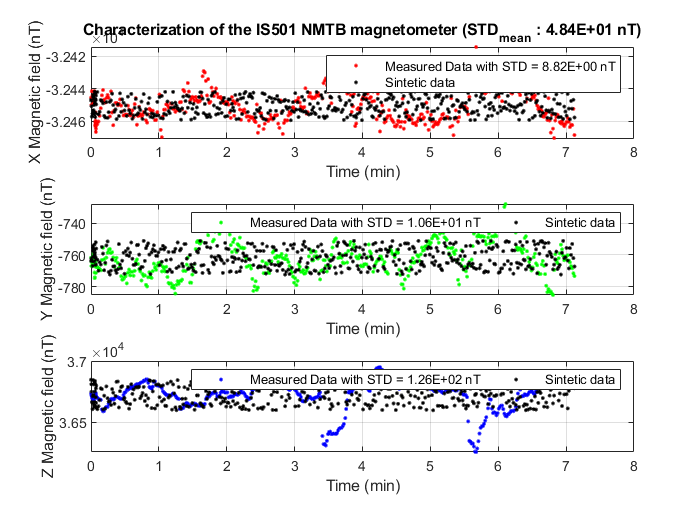

fileName = 'staticMagData_Epoch_2023_25_09';
load(fileName);
endFlag = 450;
magStd = std(staticDataStore(2:4,2:endFlag)');
%[a,b,c]=fftAalisys(2,staticDataStore(1,2:478),staticDataStore(2,2:478));
figure();
p1 = subplot(3,1,1);
h1 = plot(staticDataStore(1,1:endFlag)/60,staticDataStore(2,1:endFlag)','r.'); grid on; hold on;
h2 = plot(staticDataStore(1,1:endFlag)/60,mean(staticDataStore(2,2:endFlag))+2*magStd(1)*rand(1,endFlag)-magStd(1),'k.');
xlabel('Time (min)'); ylabel('X Magnetic field (nT)');
legend([h1,h2],['Measured Data with STD = ', num2str(magStd(1),'%.2E'),' nT'],'Sintetic data')
title(['Characterization of the IS501 NMTB magnetometer (STD_{mean} : ', num2str(mean(magStd),'%.2E'),' nT)']);

p2 = subplot(3,1,2);
h1=plot(staticDataStore(1,1:endFlag)/60,staticDataStore(3,1:endFlag)','g.'); grid on; hold on;
h2=plot(staticDataStore(1,1:endFlag)/60,mean(staticDataStore(3,2:endFlag))+2*magStd(2)*rand(1,endFlag)-magStd(2),'k.');
xlabel('Time (min)'); ylabel('Y Magnetic field (nT)');
legend([h1,h2],['Measured Data with STD = ', num2str(magStd(2),'%.2E'),' nT'],'Sintetic data','Orientation','horizontal');

p3 = subplot(3,1,3);
h1=plot(staticDataStore(1,1:endFlag)/60,staticDataStore(4,1:endFlag)','b.'); grid on; hold on;
h2=plot(staticDataStore(1,1:endFlag)/60,mean(staticDataStore(4,2:endFlag))+2*magStd(3)*rand(1,endFlag)-magStd(3),'k.');
xlabel('Time (min)'); ylabel('Z Magnetic field (nT)');
legend([h1,h2],['Measured Data with STD = ', num2str(magStd(3),'%.2E'),' nT'],'Sintetic data','Orientation','horizontal');

linkaxes([p1,p2,p3],'x');

### 2.3. Detumbling Control

In [5] it is explained that the commanding magnetic dipole.


$$m = \frac{k}{||B||}\omega \times b$$
  

Where:

- b: $\frac{B}{||B||}$

- $\omega$: Angular velocity.

- k: is a positive scalar gain.

Then the control Torque is:


$$L = \frac{k}{||B||}(\omega \times b)\times B = k (\omega \times b) \times b = -k (I_3 - b b^T)\omega$$


The control torque is clearly perpendicular to $b$. To prove the stability of this control law consider the following candidate Lyapunov function.


$$V = \frac{1}{2}\omega^TJ\omega$$


And


$$\dot{V} = -k \omega^T(I_3 - bb^T)\omega$$


Since the eigenvalues of ($I_3- b b^T$)  are always 0, 1, and 1, then $\dot{V}$ is only negative semi-definite. Stated another way, when $\omega$ is parallel to ***b ***then $\dot{V} = 0$. This is not a concern in practice, though [6].

### 2.4. Bdot Controller for detumbling 

The Detumble mode used the B-dot control law (controlling electro-magnetic dipole  moment) to make an angular velocity $\omega$ of satellite close to zero. The main mission of this  control is simply to stop the uncontrolled rotation of the satellite after separating from the  launcher, regardless of the orientation of its coordinate axes.

The torque necessary to slow down the rotation of the satellite is given by.

$\bar{T}_{req} = -K_p \dot{B}$   (2.1.2)

From eq (2.1.1) can be expressed as:

**1.3.3. Satellite Parameters**

Clear and errase variables.

clear;
clc;

global tant;
tant = 0;

- **Satellite parameters**

sat.Is = [0.103682,-0.001094, 0.015519;...
         -0.001094, 0.104158,-2.57e-6;...
          0.015519,  2.57e-6, 0.088588];
sat.mass = 40; %Kg

- **Magnetometers Parameters (Simple Model) BASED ON MQ800 Model**

actuators.magnetorquer.power            = 1536E-3;       %W
actuators.magnetorquer.MaxPower         = 13200-3;       %W
actuators.magnetorquer.voltage          = 12;            %V
actuators.magnetorquer.dimensions       = [250,67,35];   %mm
actuators.magnetorquer.nominalDipole    = 15;            %Am^2
actuators.magnetorquer.maxNominalDipole = 30;            %Am^2
actuators.magnetorquer.A  = actuators.magnetorquer.dimensions(2)*actuators.magnetorquer.dimensions(3)*1E-6;   %Transversal Area (m ^2)
actuators.magnetorquer.n  = actuators.magnetorquer.nominalDipole*actuators.magnetorquer.voltage/(actuators.magnetorquer.A*actuators.magnetorquer.power);           %Number of turns
actuators.magnetorquer.maxCurrent = actuators.magnetorquer.maxNominalDipole/actuators.magnetorquer.voltage;  %Max current (mA)

### Sensors Parameters

sensors.mag.desvEst = 50.00e-9; %T
sensors.mag.res     = 31.25e-9; %T
sensors.mag.normDesvEst =  0.5;

- **Earth Parameters**

%%%%This will define all of our planet parameters
earth.Radius       = 6378E3;               %% Planet Radius (meters)
earth.Mass         = 5.972E24;             %% Planet Mass (kg)
earth.GravityConst = 6.674E-11;            %% Planet gravity constan (Nm^2/kg^2)
earth.mu           = earth.GravityConst*earth.Mass;        %% G*M product (Nm^2/kg)

- **Orbit Parameters**

%% Orbit Parameters
%%%Orbital parameters
orbit.altitude    = 500E3;   
orbit.semiMajorAxis = orbit.altitude+earth.Radius;
orbit.eccentricity = 0;
orbit.inclination = 97.34; 
orbit.rightAscensionOfAscendingNode = 313.131; 
orbit.argumentOfPeriapsis = 0; 
orbit.trueAnomaly = 0;
orbit.period      = 2*pi/sqrt(earth.mu)*orbit.semiMajorAxis^(3/2); % Orbital period
orbit.vcircular   = sqrt(earth.mu/orbit.semiMajorAxis);            % Circular velocity

- **Satellite Disturbances**

%%% External disturbances
%disturbance = @(state) dist_gravityGrad(state,sat,orbit,earth);
disturbance = @(t) simplifiedDisturbances(t);

- **Initial conditions**

%% Initial Conditions
%%% Intitial Conditions for Attitude and Angular Velocity (Euler angles)
initial.atitude.rpy0_deg(1)    = 0;           %  Initial Roll  (deg)
initial.atitude.rpy0_deg(2)    = 0;           %  Initial Pitch (deg)
initial.atitude.rpy0_deg(3)    = 0;           %  Initial Yaw   (deg)
%%% Initial Euler Angles and quaternions
initial.atitude.rpy0_rad    = deg2rad([initial.atitude.rpy0_deg(1),...
    initial.atitude.rpy0_deg(2),...
    initial.atitude.rpy0_deg(3)]');       % Euler Angles (rad)
initial.atitude.q0123_0 = EulerAngles2Quaternions(initial.atitude.rpy0_rad);  % Quaternions
%%% Initial angular rates in the body frame (rad/s)
initial.omega.omega0_x = -1*deg2rad(3);
initial.omega.omega0_y = deg2rad(4);
initial.omega.omega0_z = -1*deg2rad(5);

## Obtain the magnetic Field

settings.B_earth_field.model_epoch = '2020';
settings.B_earth_field.decimal_year = 2020 ;
settings.wgs84 = wgs84Ellipsoid;

#### 1.3.4. Start Satellite Simulation (SPG4 propagator)

- **Simulation Settings**

%% Simulation Parameters
%%% Setting Time Window (just 5 orbit)
settings.startTime = datetime(2023,08,30,12,35,38);
settings.sampleTime = 100;
settings.number_of_orbits = 10;
settings.tfinal = orbit.period*settings.number_of_orbits;
%settings.tfinal = 2;
settings.stopTime = settings.startTime  + seconds(settings.tfinal);

%%% Satellite initial states
settings.X0 = [initial.atitude.q0123_0; initial.omega.omega0_x; ...
               initial.omega.omega0_y ; initial.omega.omega0_z];

%% Create satellite scenario to use SPG4 propagator
sc = satelliteScenario(settings.startTime ,settings.stopTime,settings.sampleTime);
sat.satSGP4 = satellite(sc, orbit.semiMajorAxis, orbit.eccentricity, orbit.inclination, ...
        orbit.rightAscensionOfAscendingNode, orbit.argumentOfPeriapsis, orbit.trueAnomaly);

- **Simulation **

%% Solve by variable step Runge Kutta of 4 order and use SPG4 propagator 
tic
opts = odeset('InitialStep',1e-4,'RelTol',1e-6);
settings.hWaitbar = waitbar(0, 'Progress: 0%','Name', 'GWSAT-1 Simulation Progress');
[tout,x] = ode45(@(t,x) satelliteSPG4sim(t, x, sat, disturbance, sensors, settings),...
    [0 settings.tfinal],settings.X0,opts);
elapsedTime = toc;

%%%%%% Recover values
%%% Create Data containers
xyzout         = zeros(length(x),3);
mag_field      = zeros(3,length(x));
mag_field_meas = zeros(3,length(x));
Torque_mag_v = zeros(3,length(x));
m_mag_v      = zeros(3,length(x));
mag_currents = zeros(3,length(x));
dis_v = zeros(3,length(x));
k_v = zeros(1,length(x));
for i = 1:length(x)
    %%% Recover time %%%
    t = tout(i);
    datetime_t  = settings.startTime  + seconds(tout(i));
    %%% Recover disturance %%%
    dis_v(:,i)  = disturbance(t);
    %%% Get state in geodetic and inertial reference frames.
    [xyzout(i,:), ~] = states(sat.satSGP4,datetime_t,"CoordinateFrame", "inertial");
    gwsatEcef = eci2ecef(datevec(datetime_t),xyzout(i,:));
    llaSPG4 = ecef2lla(gwsatEcef', 'WGS84');

    %%% Use LLA to get value models of magnetic field (XYZ in NED frame) 
    [B_ref, ~, ~, dip, ~] = wrldmagm(llaSPG4(3), llaSPG4(1),llaSPG4(2),...
             settings.B_earth_field.decimal_year, settings.B_earth_field.model_epoch);  
   
    %%% Turn reference to BodyFrame
    mag_field(:,i) = quatRotation(quatconj(x(i,1:4))', B_ref*1E-9);
    %%% Apply magnetic model
    mag_field_meas(:,i) = mag_model(mag_field(:,i),sensors.mag.desvEst,sensors.mag.res);
    
    %%% Obtain control Torque
    %orbitPeriod = settings.tfinal/settings.number_of_orbits;
    %k = 2*(2*pi/5.677016087140827e+03)*(1+sin(deg2rad(dip)))*min(diag(sat.Is));
    k_v(i)= 2*(2*pi/5.677016087140827e+03)*(1+sin(deg2rad(dip)))*min(0.0789)*8e9;
    %k_v(i)= 2.5e6;
    %k=0.25E6;
    [Torque_mag_v(:,i), m_mag_v(:,i)] = detumblingControl(x(i,:)', k_v(i), mag_field_meas(:,i));
    %%% Obtain currents based on model
    mag_currents(:,i) = m_mag_v(:,i)/(actuators.magnetorquer.n*actuators.magnetorquer.A);
    %%TotalTorque = dis_v(:,i)+Torque_mag_v(:,i);
end

% Print the elapsed time in seconds
% fprintf('Elapsed time: %.3f miliseconds\n',elapsedTime*1000);

Plot new figures with the new project

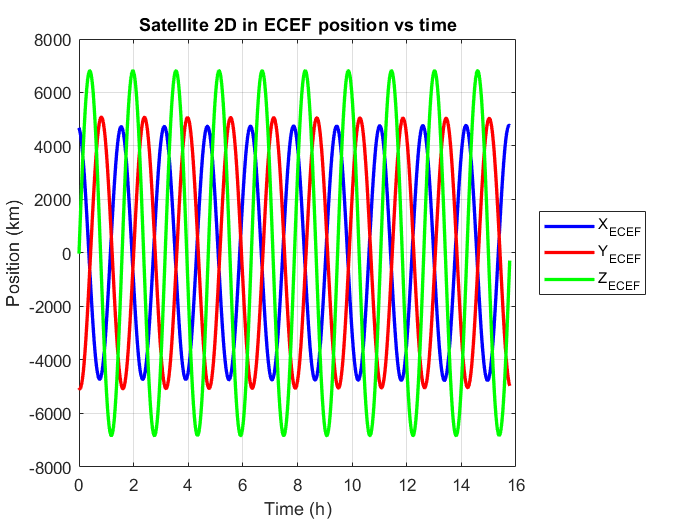

% Rename index
q0123out = x(:,1:4);                           %%Satellite quaternions
ptpout = Quaternions2EulerAngles(q0123out);    %%Satellite euler angles
pqrout = x(:,5:7);                             %%Angular Rates

% Program containers
magnOmega=zeros(1,length(x));
for i = 1:length(x)
    magnOmega(:,i) = norm(x(i,5:7)); 
end

%% Plot 2D position
%%%Plot satellite position as a function of time
figure();
    h1 = plot(tout/3600,xyzout(:,1)/1E3,'b-','LineWidth',2); hold on; grid on;
    h2 = plot(tout/3600,xyzout(:,2)/1E3,'r-','LineWidth',2);
    h3 = plot(tout/3600,xyzout(:,3)/1E3,'g-','LineWidth',2);
    xlabel('Time (h)'); ylabel('Position (km)');
    legend([h1,h2,h3],'X_{ECEF}','Y_{ECEF}','Z_{ECEF}','Location','eastoutside');
    title('Satellite 2D in ECEF position vs time');

figure();

% Ejemplo en MATLAB asumiendo que 'signal' es tu señal y 'lower' y 'upper' son los límites de la franja
[stx,indexX]=obtainStableTime(tout/3600, rad2deg(pqrout(:,1)), -0.1, 0.1);
[sty,indexY]=obtainStableTime(tout/3600, rad2deg(pqrout(:,2)), -0.1, 0.1);
[stz,indexZ]=obtainStableTime(tout/3600, rad2deg(pqrout(:,3)), -0.1, 0.1);
 [porcentaje_en_franjax] = percentageOfSignarl(rad2deg(pqrout(9129:end,1)),  -0.1, 0.1) 

porcentaje_en_franjax = 8.7969

[porcentaje_en_franjay] = percentageOfSignarl(rad2deg(pqrout(9129:end,2)),  -0.1, 0.1) 

porcentaje_en_franjay = 54.5411

[porcentaje_en_franjaz] = percentageOfSignarl(rad2deg(pqrout(9129:end,3)),  -0.1, 0.1) 

porcentaje_en_franjaz = 31.8382

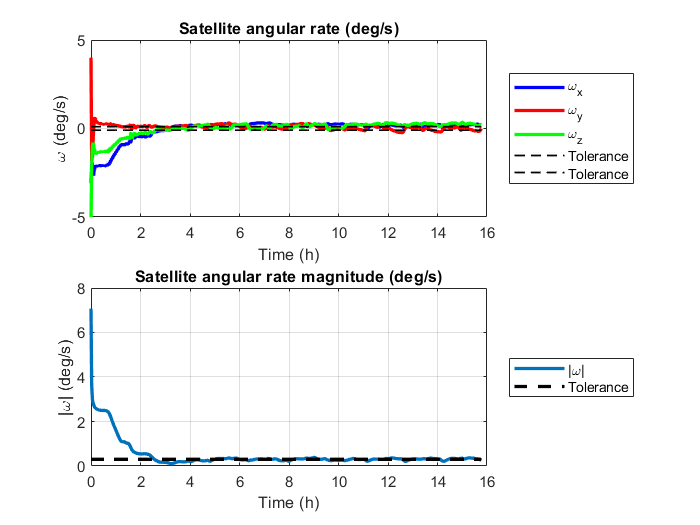

    
p1 = subplot(2,1,1);
    h1 = plot(tout/3600,rad2deg(pqrout(:,1)),'b-','LineWidth',2); hold on; grid on
    h2 = plot(tout/3600,rad2deg(pqrout(:,2)),'r-','LineWidth',2);
    h3 = plot(tout/3600,rad2deg(pqrout(:,3)),'g-','LineWidth',2);
    max = 0.1*ones(1,length(tout));
    h4 = plot(tout/3600,max,'k--','LineWidth',1);
    h5 = plot(tout/3600,-1*max,'k--','LineWidth',1);
    xlabel('Time (h)'); ylabel('\omega (deg/s)');
    legend([h1,h2,h3,h4,h5],'\omega_x','\omega_y','\omega_z','Tolerance','Tolerance','Location','eastoutside');
    title('Satellite angular rate (deg/s)');
    %xlim([0.0 5.0]);

p2 = subplot(2,1,2);
    h1 = plot(tout/3600,rad2deg(magnOmega),'LineWidth',2); hold on; grid on;
    max = 3*0.1*ones(1,length(tout));
    h2 = plot(tout/3600,max,'k--','LineWidth',2);
    xlabel('Time (h)'); ylabel('|\omega| (deg/s)');
    title('Satellite angular rate magnitude (deg/s)');
    %xlim([0.0 5.0]);
    legend([h1,h2],'|\omega|','Tolerance','Location','eastoutside');
linkaxes([p1,p2],'x')

[porcentaje_en_franjaMag] = percentageOfSignarl(rad2deg(magnOmega(9129:end)),  0, 0.3);

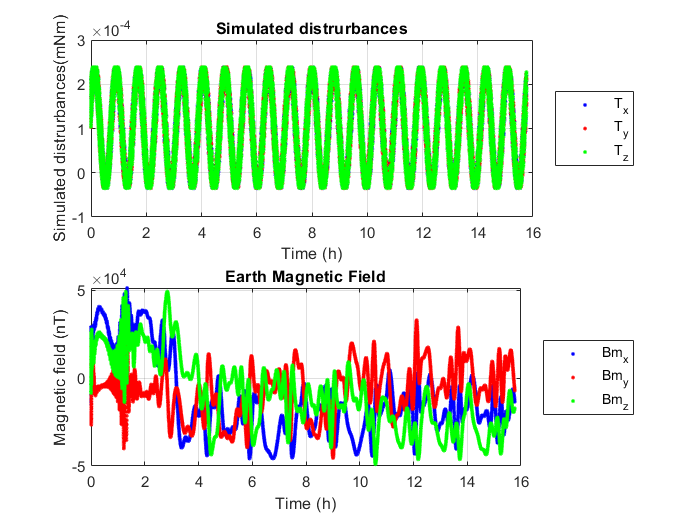

figure(); 
p1 = subplot(2,1,1);
    h1 = plot(tout/3600,dis_v(1,:)*1E3,'b.','LineWidth',2); hold on; grid on;
    h2 = plot(tout/3600,dis_v(2,:)*1E3,'r.','LineWidth',2);
    h3 = plot(tout/3600,dis_v(3,:)*1E3,'g.','LineWidth',2);
    xlabel('Time (h)'); ylabel('Simulated distrurbances(mNm)');
    legend([h1,h2,h3],'T_x','T_y','T_z','Location','eastoutside');
    title('Simulated distrurbances');
 
 p2 = subplot(2,1,2);
    %%%Real data
    %h1 = plot(tout/3600,mag_field(1,:)*1E9,'c--','LineWidth',1); hold on; grid on;
    %h2 = plot(tout/3600,mag_field(2,:)*1E9,'m--','LineWidth',1);
    %h3 = plot(tout/3600,mag_field(3,:)*1E9,'k--','LineWidth',1);
    %%%Measures values
    h4 = plot(tout/3600,mag_field_meas(1,:)*1E9,'b.','LineWidth',1);  hold on; grid on;
    h5 = plot(tout/3600,mag_field_meas(2,:)*1E9,'r.','LineWidth',1);
    h6 = plot(tout/3600,mag_field_meas(3,:)*1E9,'g.','LineWidth',1);
    xlabel('Time (h)'); ylabel('Magnetic field (nT)');
    legend([h4,h5,h6],'Bm_x','Bm_y','Bm_z','Location','eastoutside');        
    title('Earth Magnetic Field');
linkaxes([p1,p2],'x');

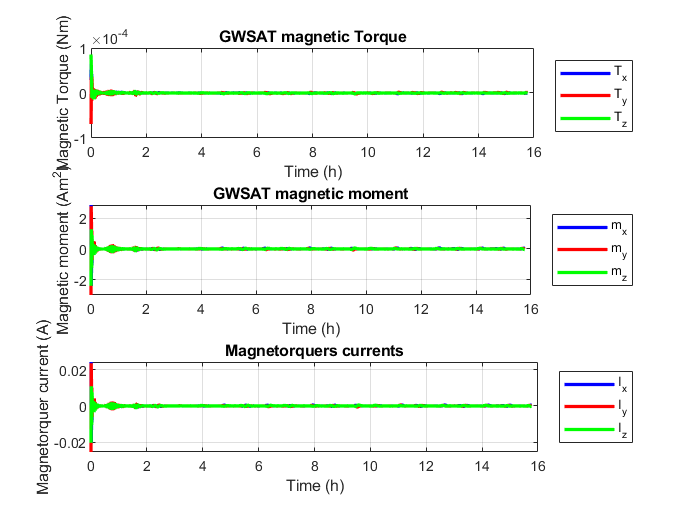

figure()
p1 = subplot(3,1,1);
    h1 = plot(tout/3600,Torque_mag_v(1,:),'b-','LineWidth',2); hold on; grid on
    h2 = plot(tout/3600,Torque_mag_v(2,:),'r-','LineWidth',2);
    h3 = plot(tout/3600,Torque_mag_v(3,:),'g-','LineWidth',2);
    legend([h1,h2,h3],'T_x','T_y','T_z','Location','eastoutside');
    xlabel('Time (h)'); ylabel('Magnetic Torque (Nm)');
    title('GWSAT magnetic Torque');
    
p2 = subplot(3,1,2);
    h1 = plot(tout/3600,m_mag_v(1,:),'b-','LineWidth',2); hold on; grid on
    h2 = plot(tout/3600,m_mag_v(2,:),'r-','LineWidth',2);
    h3 = plot(tout/3600,m_mag_v(3,:),'g-','LineWidth',2);
    legend([h1,h2,h3],'m_x','m_y','m_z','Location','eastoutside');
    xlabel('Time (h)'); ylabel('Magnetic moment (Am^2)');
    title('GWSAT magnetic moment');

p3 = subplot(3,1,3);
    h1 = plot(tout/3600,mag_currents(1,:),'b-','LineWidth',2); hold on; grid on
    h2 = plot(tout/3600,mag_currents(2,:),'r-','LineWidth',2);
    h3 = plot(tout/3600,mag_currents(3,:),'g-','LineWidth',2);
    legend([h1,h2,h3],'I_x','I_y','I_z','Location','eastoutside');
    xlabel('Time (h)'); ylabel('Magnetorquer current (A)');
    title('Magnetorquers currents');
linkaxes([p1,p2,p3],'x');

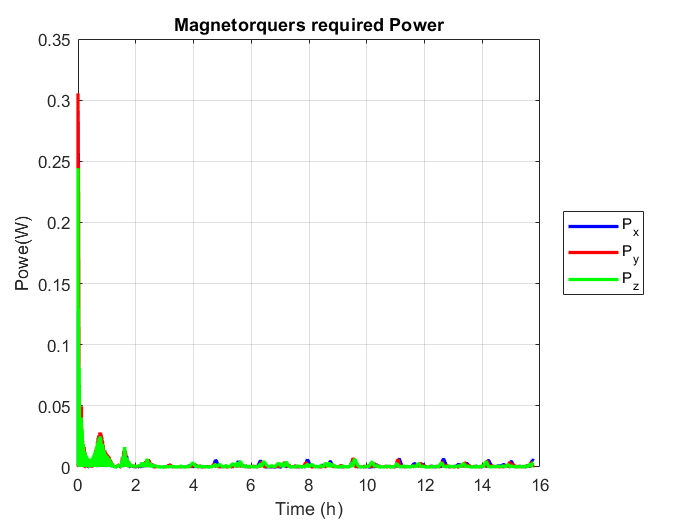


figure();
    h1 = plot(tout/3600,abs(mag_currents(1,:))*12,'b-','LineWidth',2); hold on; grid on
    h2 = plot(tout/3600,abs(mag_currents(2,:))*12,'r-','LineWidth',2);
    h3 = plot(tout/3600,abs(mag_currents(3,:))*12,'g-','LineWidth',2);
    legend([h1,h2,h3],'P_x','P_y','P_z','Location','eastoutside');
    xlabel('Time (h)'); ylabel('Powe(W)');
    title('Magnetorquers required Power');

%%Calculate Average power
powerX = potenciaMedia(tout(1:9129)',mag_currents(1,1:9129));
powerY = potenciaMedia(tout(1:9129)',mag_currents(2,1:9129));
powerZ = potenciaMedia(tout(1:9129)',mag_currents(3,1:9129)); 

TotalPower = powerX+powerY+powerZ;

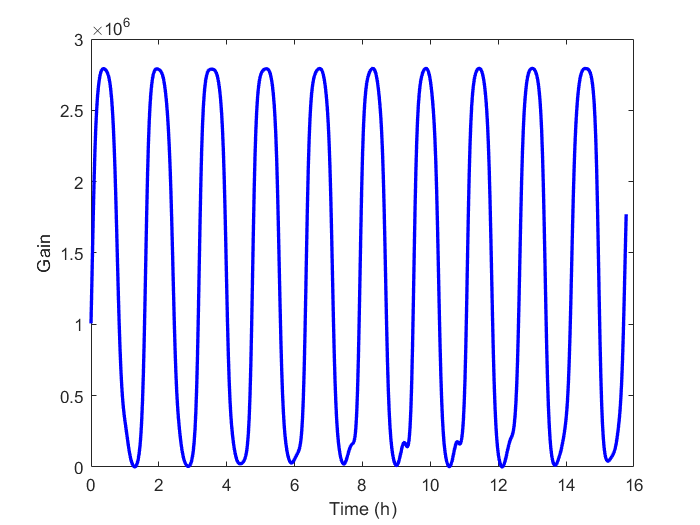

figure()
h1 = plot(tout/3600,k_v,'b-','LineWidth',2);
xlabel('Time (h)'); ylabel('Gain');


% % % % % % figure()
% % % % % % scaleFrames = 5E-4;
% % % % % % scaleAngRate = 1;
% % % % % % scaleTgg = 1E4;
% % % % % % 
% % % % % % %% Rename index
% % % % % % %xyzout =   x(:,1:3);                            %%Satellite position(m)
% % % % % % %q0123out = x(:,7:10);                           %%Satellite quaternions
% % % % % % %ptpout = Quaternions2EulerAngles(q0123out);     %%Satellite euler angles
% % % % % % %pqrout = x(:,11:13);                            %%Angular Rates
% % % % % % 
% % % % % % %%% Plot inertia frame I (ECEF)
% % % % % % [h1,~] = plotVector(zeros(1,3), [1,0,0], scaleFrames, 'k--', 'X_I', 'e'); hold on
% % % % % % plotVector(zeros(1,3), [0,1,0], scaleFrames, 'k--', 'Y_I', 'e');
% % % % % % plotVector(zeros(1,3), [0,0,1], scaleFrames, 'k--', 'Z_I', 'e');
% % % % % % plotPoint (zeros(1,3), 'k.', 'O_I', -0.08);
% % % % % % 
% % % % % % %%% Plot angular rate
% % % % % % %pqrout = x(:,11:13);  
% % % % % % [h2,  h3]  = plotVector(zeros(1,3), quatRotation(q0123out(1,:)',pqrout(1,:)') ,scaleAngRate,'b-','\omega','e');
% % % % % % wout_i_V = struct();
% % % % % % 
% % % % % % %%% Plot magnetorquers torque
% % % % % % [h13,  h14]  = plotVector(zeros(1,3), quatRotation(q0123out(1,:)',Torque_mag_v(1,:)') ,scaleAngRate,'k-','T_c','e');
% % % % % % tMag_i_V = struct();
% % % % % % 
% % % % % % %%% Plot Body Frame
% % % % % % [h4,  h5]  = plotVector(zeros(1,3), quatRotation(q0123out(1,:)',[1,0,0]'),scaleFrames, 'r-', 'X_B', 'e');
% % % % % % [h6,  h7]  = plotVector(zeros(1,3), quatRotation(q0123out(1,:)',[0,1,0]'),scaleFrames, 'r-', 'Y_B', 'e');
% % % % % % [h8,  h9]  = plotVector(zeros(1,3), quatRotation(q0123out(1,:)',[0,0,1]'),scaleFrames, 'r-', 'Z_B', 'e');
% % % % % % tgg_v = struct();
% % % % % % 
% % % % % % %%% Plot External torque
% % % % % % [h10,  h11]  = plotVector(zeros(1,3), quatRotation(q0123out(1,:)', dis_v(:,1)),scaleTgg, 'c-', 'T_gg', 'e');
% % % % % % 
% % % % % % xlim([-6E-4 6E-4]);
% % % % % % ylim([-6E-4 6E-4]);
% % % % % % zlim([-6E-4 6E-4]);
% % % % % % 
% % % % % % ri_v = struct();
% % % % % % for i = 1:length(x)
% % % % % %         %Calculate rotation Matrix arround u axis
% % % % % %         axisx = quatRotation(q0123out(i,:)',[1,0,0]');
% % % % % %         axisy = quatRotation(q0123out(i,:)',[0,1,0]');
% % % % % %         axisz = quatRotation(q0123out(i,:)',[0,0,1]');
% % % % % %         ri_v.(['n_',num2str(i)]) = [axisx',axisy',axisz'];
% % % % % %         %Calculate rotated angular rate
% % % % % %         wout_i = quatRotation(q0123out(i,:)',pqrout(i,:)');
% % % % % %         wout_i_V.(['n_',num2str(i)]) = wout_i';
% % % % % %         %Calculate rotated Grav Gradient
% % % % % %         tgg_i = quatRotation(q0123out(i,:)',dis_v(:,i)');
% % % % % %         tgg_v.(['n_',num2str(i)]) = tgg_i';
% % % % % %         %Calculate rotated Magnetic Torque
% % % % % %         tmag_i = quatRotation(q0123out(i,:)',Torque_mag_v(:,i)');
% % % % % %         tMag_i_V.(['n_',num2str(i)]) = tmag_i';
% % % % % % end
% % % % % % 
% % % % % % for i =  1:length(x)
% % % % % %     Wb  = wout_i_V.(['n_',num2str(i)])*scaleAngRate;
% % % % % %     B   = ri_v.(['n_',num2str(i)])*scaleFrames;
% % % % % %     tgg = tgg_v.(['n_',num2str(i)])*scaleTgg;
% % % % % %     tmag = tMag_i_V.(['n_',num2str(i)])*scaleTgg;
% % % % % %     
% % % % % %     h12 = plot3(Wb(1),Wb(2),Wb(3),'g.');
% % % % % %     
% % % % % %     set(h2, 'UData', Wb(1), 'VData', Wb(2), 'WData', Wb(3));
% % % % % %     set(h3, 'Position', Wb);
% % % % % %     
% % % % % %     set(h4, 'UData', B(1,1), 'VData', B(2,1), 'WData', B(3,1));      
% % % % % %     set(h5, 'Position', B(:,1));
% % % % % %     
% % % % % %     set(h6, 'UData', B(1,2), 'VData', B(2,2), 'WData', B(3,2));      
% % % % % %     set(h7, 'Position', B(:,2));
% % % % % %     
% % % % % %     set(h8, 'UData', B(1,3), 'VData', B(2,3), 'WData', B(3,3));      
% % % % % %     set(h9, 'Position', B(:,3));
% % % % % %     
% % % % % %     set(h10, 'UData', tgg(1), 'VData', tgg(2), 'WData', tgg(3));
% % % % % %     set(h11, 'Position', tgg);
% % % % % %     
% % % % % %     set(h13, 'UData', tmag(1), 'VData', tmag(2), 'WData', tmag(3));
% % % % % %     set(h14, 'Position', tmag);
% % % % % %     
% % % % % %     %%% Pause animation
% % % % % %     pause(0.001);
% % % % % % end

function [x_dot] = mySatelliteSPG4(t, x, sat, Td)
%%% Inputs
% t: current time
% x: satellite state
% sat: Satellite parameters
% earth: Earth parameters
% Td: External Disturbances

%%% Read state input
q   =  x(1:4);
w   =  x(5:7);

%% Read Satellite physical parameters
%m  = sat.mass;
Is = sat.Is;

%%%Rotational Dynamics
%%Book: Fundamentals of Spacecraft Attitude Determination and Control
%%Author: F. Landis Markley & John L. Crassidis
%%Quaternions Kinematics..Ecuación (2.88)
Xi=[-q(2),-q(3),-q(4);
    q(1),-q(4),q(3);
    q(4),q(1),-q(2);
    -q(3),q(2),q(1)];
q_dot=1/2*Xi*w;
%%%Kynematics Equation(3.21)
H = Is*w;                         %Satellite Angular momentun
w_dot = Is\(Td - cross(w,H));     %Dynamics Equatión (3.147)
%%%x_dot Vector
x_dot=[q_dot;w_dot];
end

function [x_dot] = satelliteSPG4sim(t, x, sat, dist, sensors, settings)
%%Global variables
%global tant;

%% Disturbances
%LS2125204: Brayan Espinoza

%%% Calculate dt
%dt = t - tant;

%%% Update time vector
datetime_t = settings.startTime  + seconds(t);
%%% Get distubance
%T_disturbances = dist([zeros(6,1);x]);
%%% Use Simplified disturbances
T_disturbances = dist(t);
%T_disturbances = [0,0,0]';

%%% Get state in geodetic and inertial reference frames.
%[positionGCRF, velGCRF] = states(sat.satSGP4,datetime_t,"CoordinateFrame", "inertial");
[positionGCRF, ~] = states(sat.satSGP4, datetime_t, "CoordinateFrame", "inertial");
r_ecef = eci2ecef(datevec(datetime_t),positionGCRF);
llaSPG4 = ecef2lla(r_ecef', 'WGS84');

%%%Create a rotation matrix from the NED frame to the GCRF inertial frame
%phiE = 0;
%thetaE = acos(positionGCRF(3)/norm(positionGCRF));
%psiE = atan2(positionGCRF(2),positionGCRF(1));
%%%Got the inertial Rotation matrix
%rot_NED_I = TIB(phiE,thetaE+pi,psiE);   

% %%% Get rotation quaternion from NED to orbit frame
% D_v = [0,0,1]';
% A = norm(cross(rot_NED_I(:,1),getUnitVector(velGCRF)));
% B = dot(rot_NED_I(:,1),getUnitVector(velGCRF));
% angle = atan2(A,B);
% q_NED_o = [cos(angle/2), D_v(1)*sin(angle/2), D_v(2)*sin(angle/2), D_v(3)*sin(angle/2)]; 

%%% Use LLA to get value models of magnetic field (XYZ in NED frame) 
% [xyz, ~, ~, ~, ~] = wrldmagm(llaSPG4(3), llaSPG4(1),llaSPG4(2),...
%         settings.B_earth_field.decimal_year, settings.B_earth_field.model_epoch);             
%     
[B_ref, ~, ~, dip, ~] = wrldmagm(llaSPG4(3), llaSPG4(1),llaSPG4(2),...
         settings.B_earth_field.decimal_year, settings.B_earth_field.model_epoch);  

%%% Turn NED frame into Orbit frame
%B_ref = quatRotation(q_NED_o,xyz)*1E-9; %In Teslas
%%% Turn reference to BodyFrame
B_body = quatRotation(quatconj(x(1:4)'), B_ref*1E-9);
%%% Apply magnetic model
mag_bm = mag_model(B_body,sensors.mag.desvEst,sensors.mag.res);

%%% Satellite model
%orbitPeriod = settings.tfinal/settings.number_of_orbits;
%k = 2*(2*pi/5.677016087140827e+03)*(1+sin(deg2rad(dip)))*min(diag(sat.Is))*5E9;       %5E9
k = 2*(2*pi/5.677016087140827e+03)*(1+sin(deg2rad(dip)))*min(0.0789)*8e9;
%k=0.25E6;
[T_control,~] = detumblingControl(x,k,mag_bm);
TotalTorque = T_disturbances+T_control';
%T_control;
x_dot = mySatelliteSPG4(t, x, sat, TotalTorque);

%%% Progress bar configuration
%%%% Calculate the progress percentage
progress = t / settings.tfinal;

if isa(settings.hWaitbar,'handle') && isvalid(settings.hWaitbar)
    if t == settings.tfinal
        % Close the progress bar when the simulation is complete
        close(settings.hWaitbar);
    else
        % Update the progress bar
        waitbar(progress, settings.hWaitbar, sprintf('Progress: %.1f%%', progress*100));
    end
end
%tant = t;
end

function Tgg = dist_gravityGrad(state,sat,orbit,earth)
% This function calculates the torque produced by the earth's gravity
% gradient.

%% Read inputs
q0123=state(7:10);

%% Gravity disturbances
%R = param{1,2};
%altitude = param{1,3};
%I = param{1,4};

%% Perform calculations (review)
rc = earth.Radius + orbit.altitude;
wo2=3.9833e+14/rc^3;
c3=[2*(q0123(2)*q0123(4)-q0123(3)*q0123(1));
    2*(q0123(3)*q0123(4)+q0123(2)*q0123(1));
    1-2*(q0123(2)^2+q0123(3)^2)];
Tgg = cross(3*wo2*c3,sat.Is*c3);
end

function [Tc,muB] = detumblingControl(state,k,B_body)
 %% Earth magnetic field expresend in the body Frame
omega = state(5:7); 
muB = k*cross(omega,B_body);
%muB = saturate(muB, 30, 30);
Tc = cross(muB,B_body);
end

function mag_bm = mag_model(mag_b,sig_tam,sig_res)
    %%-----------magnetometerc Model------------
    %%%Add random noise
    mag_b_noise=mag_b+sig_tam*randn(1,3);
    %%%Add resolution
    mag_bm=[round(mag_b_noise(1)/sig_res)*sig_res,...
            round(mag_b_noise(2)/sig_res)*sig_res,...
            round(mag_b_noise(3)/sig_res)*sig_res];   
end

function rotX = quatRotation(q,x)
    qx = [0,x(1),x(2),x(3)];
    [a,b]=size(q);
    if a == 4 && b == 1
        q = q';
    end
    qrotX = quatmultiply(quatmultiply(q, qx), quatconj(q));
    %qrotX = QuaternionsMultiplication(QuaternionsMultiplication(q,qx),QuaternionsConjugate(q));
    rotX = qrotX(2:4);
end

%% Plot functions
function [h1,h2] = plotVector(v0,v,scale,style,label,labelLocation)
if labelLocation=='m'
    scale = scale*1.1;
    h1 = quiver3(v0(1), v0(2), v0(3), v(1)*scale, v(2)*scale, v(3)*scale, style);
    h2 = text(v0(1)+v(1)*scale/2,v0(2)+v(2)*scale/2, v0(3)+v(3)*scale/2, label,'Color',style(1));
else
    h1 = quiver3(v0(1)*scale, v0(2)*scale, v0(3)*scale, v(1)*scale, v(2)*scale, v(3)*scale, style);
    h2 = text((v0(1)+v(1))*scale, (v0(2)+v(2))*scale, (v0(3)+v(3))*scale, label,'Color',style(1));
end

% Set equal axis scales and display grid
axis equal
grid on
end

function [h1,h2] = plotPoint(P,style,label,pos)
    h1 = plot3(P(1),P(2),P(3),style);
    h2 = text(P(1)+pos,P(2)+pos,P(3)+pos,label,'Color',style(1));
end

% % function h1 = plotAngle(center,radius,v1,v2,angle,style)
% % 
% % angPlot = [];
% % 
% % normalVector = cross(v1,v2)/norm(cross(v1,v2));
% % v = null(normalVector);
% % ang = asin (norm(cross(v(:,1),v1))/(norm(v(:,1))*norm(v1)));
% % %ang = atan2(v(2,1),v(1,1))-atan2(v1(2),v1(1));
% % 
% % %Calcula el cuaternión que reprónesenta la rotacion
% % q = [cos(ang/2), normalVector(1)*sin(ang/2), normalVector(2)*sin(ang/2), normalVector(3)*sin(ang/2)];
% % 
% % % Generate points in oblique plane
% % theta = linspace(0, angle, 100);
% % points_on_circle = radius * (v(:,1)* cos(theta) + v(:,2) * sin(theta));
% % for i = 1:length(points_on_circle)
% %     angPlot = [angPlot, center' + quatRotation(quatconj(q),points_on_circle(:,i))'];
% % end
% % 
% % h1 = plot3(angPlot(1,:), angPlot(2,:), angPlot(3,:), style);
% % end

function u = getUnitVector(vector)
    u = vector/norm(vector);
end

function [tiempo_inicio, index] = obtainStableTime(time, signal, lowerLimit, upperLimit)
    % Supongamos que 'time' es el vector de tiempo y 'signal' es la señal
    % 'lower' y 'upper' son los límites de la franja

    % Encuentra los índices donde la señal está dentro de la franja
    indices_en_franja = find(signal >= lowerLimit & signal <= upperLimit);

    % Verifica si la señal entra en la franja en algún momento
    if ~isempty(indices_en_franja)
        % Encuentra el tiempo correspondiente a los primeros y últimos índices en la franja
        index = indices_en_franja(1);
        tiempo_inicio = time(index);
        %tiempo_final = time(indices_en_franja(end));

        %% Calcula la duración en la franja
        %duracion_en_franja = tiempo_final - tiempo_inicio;

        %disp(['La señal está dentro de la franja desde ', num2str(tiempo_inicio), ' hasta ', num2str(tiempo_final)]);
        %disp(['La duración en la franja es ', num2str(duracion_en_franja), ' unidades de tiempo.']);
    else
        disp('La señal no está dentro de la franja en ningún momento.');
    end
end

function [porcentaje_en_franja] = percentageOfSignarl(signal, lowerRange, upperRange) 
    % Ejemplo en MATLAB asumiendo que 'signal' es tu señal y 'lower' y 'upper' son los límites de la franja
    in_range = (signal >= lowerRange) & (signal <= upperRange);
    puntos_en_franja = sum(in_range);
    total_puntos = length(signal);
    porcentaje_en_franja = (puntos_en_franja / total_puntos) * 100;
end

function [top_three_pks, top_three_freq, constant] = fftAalisys(t_start,tout,normTtorque)
    % Interpolación para tener un muestreo uniforme
    %t_start = 90;  % hours
    %t_start_seconds = find(abs(t_start -(tout)) < 1e-4);
    t_start_seconds = t_start;
    temp = diff(tout(t_start_seconds(end):end));
    t_sample = min(temp(1:end-1));
    t_uniform = tout(t_start_seconds(end)):t_sample:tout(end);  % Definir un vector de tiempo uniforme
    
    x_uniform = interp1(tout(t_start_seconds(end):end), normTtorque(t_start_seconds(end):end), t_uniform, 'spline');  % Interpolación
     
    % Calcular la FFT de la señal uniforme
    Fs = 1 / (t_uniform(2) - t_uniform(1));  % Frecuencia de muestreo
    L = length(x_uniform);  % Longitud de la señal
    Y = fft(x_uniform);
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(L/2))/L;
     
    % Encontrar los picos
    [pks, locs] = findpeaks(P1);
    % Ordenar los picos en orden descendente por valor
    [sorted_pks, sorted_idx] = sort(pks, 'descend');
    % Seleccionar los tres valores más altos
    top_three_pks = sorted_pks(1:3);
    top_three_locs = locs(sorted_idx(1:3));
    top_three_freq = f(top_three_locs);
    
    %Add constant component
    constant = P1(1);
    
    % Graficar la FFT
    figure
    plot(f, P1);hold on;
    plot(top_three_freq, top_three_pks, 'ro', 'MarkerSize', 10);  % Marcadores rojos en los picos
    title('GWSAT-1 Total Disturbance FFT');
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    %text(6E-4,1.0E-7,['a_1 = ', num2str(top_three_pks(1),'%.2E'),' \cdot sin( 2 \pi ',num2str(top_three_freq(1),'%.2E'),' t)']);  % Función sinusoidal
    %text(6E-4,0.8E-7,['a_2 = ', num2str(top_three_pks(2),'%.2E'),' \cdot sin( 2 \pi ',num2str(top_three_freq(2),'%.2E'),' t)']);
    %text(6E-4,0.6E-7,['a_3 = ', num2str(top_three_pks(3),'%.2E'),' \cdot sin( 2 \pi ',num2str(top_three_freq(3),'%.2E'),' t)']);
    %text(6E-4,0.4E-7,['TDT = (a_1 + a_2 +a_3 + ',num2str(constant,'%.2E'),') N.m'])
%sen2 = top_three_pks(2)*sin(2*pi*top_three_freq(2)*t_uniform);  % Función sinusoidal
%sen3 = top_three_pks(3)*sin(2*pi*top_three_freq(3)*t_uniform);  % Función sinusoidal)
    grid on;
    %xlim([0.000000 0.001036]);ylim([0.000000000 0.000000109])
end

function potencia_media_rectangular = potenciaMedia(t,intensity)
% Supongamos que tienes una señal de corriente en el vector i y el vector de tiempo t

% Calcula la potencia media utilizando la regla del punto medio
dt = diff(t);
%t_midpoints = t(1:end-1) + dt/2;
potencia_media_rectangular = sum(intensity(1:end-1).^2 .* dt) / (t(end) - t(1));

%disp(['Potencia Media (Método Rectangular): ', num2str(potencia_media_rectangular), ' vatios']);
end 

## **Bibliograpy**

[1] Yoon, H., Seo, H. H., & Choi, H. T. (2014). Optimal uses of reaction wheels in the pyramid configuration using a new minimum infinity-norm solution. *Aerospace Science and Technology*, *39*, 109-119.

[2] Sidi, M. J. (1997). *Spacecraft dynamics and control: a practical engineering approach* (Vol. 7). Cambridge university press.

[3] [5.2b. Elipsoide de inercia. - YouTube](https://www.youtube.com/watch?v=OrGo33sSGw0&ab_channel=V%C3%ADdeosdocentesdeIsraelCa%C3%B1am%C3%B3nValera)

[4] [Transport Theorem Worked Examples | Vector Derivatives When Frames are Rotating and Translating - YouTube](https://www.youtube.com/watch?v=RpavqEtXoXk&ab_channel=Dr.ShaneRoss)

[5] Markley, F. Landis, and John L. Crassidis. *Fundamentals of spacecraft attitude determination and control*. Vol. 1286. New York, NY: Springer New York, 2014.

[6]Flores, R., Burhani, B. M., & Fantino, E. (2021). A method for accurate and efficient propagation of satellite orbits: A case study for a Molniya orbit. *Alexandria Engineering Journal*, *60*(2), 2661-2676.